ParentDir = "D:\YuLab\Work\GPS\Video";
AnmDir = uigetdir(ParentDir, "Choose animal directionory");

TrajGroupClassFile = dir(AnmDir+"\*TrajGroupClass*.mat");
if length(TrajGroupClassFile)>1
    fprintf("More than one TrajGroupClass found");
    return;
end

load(fullfile(AnmDir, TrajGroupClassFile.name));


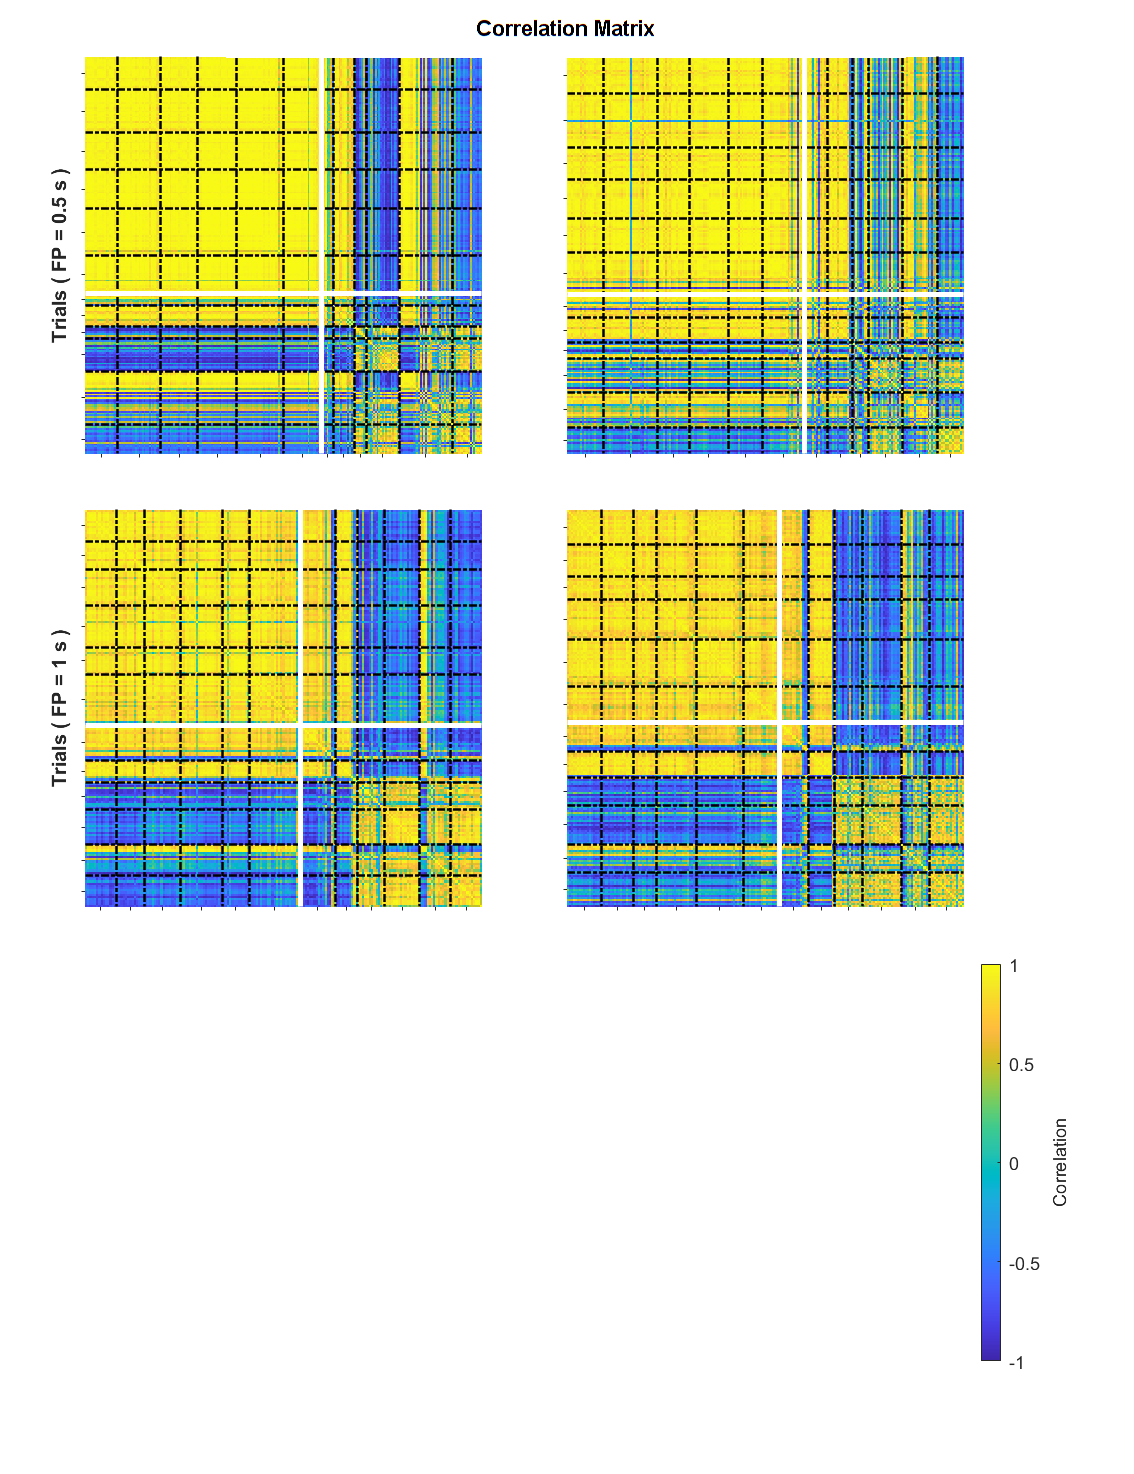

mycolormap = "parula";

fig_rsm = figure(51); clf(51);
set(fig_rsm, 'Units', 'Centimeters', 'Position', [1 1 20 26], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_rsm, 'units', 'normalized', 'position', [0.2 0.96 0.6 0.03],...
    'string', "Correlation Matrix", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

for i = 1:2

    for j = 1:2

        ax_rsm = axes;
        set(ax_rsm, 'Units', 'Centimeters', 'Position', [1.5+8.5*(j-1) 18-8*(i-1) 7 7], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'YDir', 'reverse');

        these_trials = find(obj.TrialInfo.Performance=="Correct" & obj.TrialInfo.PortChosen==obj.Ports(j) & obj.TrialInfo.FP==obj.MixedFPs(i) & obj.TrialInfo.Stage==1);

        these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
        sessions_control = obj.TrialInfo.Session(these_trials_control);
        sessions_control_id = unique(sessions_control);
        num_trials_control = zeros(length(sessions_control_id), 1);
        for k = 1:length(sessions_control_id)
            num_trials_control(k) = sum(sessions_control==sessions_control_id(k));
        end

        these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");
        sessions_chemo = obj.TrialInfo.Session(these_trials_chemo);
        sessions_chemo_id = unique(sessions_chemo);
        num_trials_chemo = zeros(length(sessions_chemo_id), 1);
        for k = 1:length(sessions_chemo_id)
            num_trials_chemo(k) = sum(sessions_chemo==sessions_chemo_id(k));
        end

        session_seps = cumsum([num_trials_control; num_trials_chemo]) + 0.5;

        M = obj.AngleHeadMatIn([these_trials_control; these_trials_chemo], 100:100+1000*obj.MixedFPs(i));

        M_dist = corrcoef(M');

        colormap(mycolormap);
        imagesc(M_dist); clim([-1 1]);

        xline(session_seps(1:end-1), 'LineStyle', '-.', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);
        yline(session_seps(1:end-1), 'LineStyle', '-.', 'LineWidth', 1.2, 'Color', 'k', 'Alpha', 1);

        xline(length(these_trials_control)+0.5, 'LineStyle', '-', 'LineWidth', 2.5, 'Color', 'w', 'Alpha', 1);
        yline(length(these_trials_control)+0.5, 'LineStyle', '-', 'LineWidth', 2.5, 'Color', 'w', 'Alpha', 1);

        xlim([.5 length(these_trials)+.5]);
        ylim([.5 length(these_trials)+.5]);

        xticks(session_seps - [num_trials_control; num_trials_chemo] / 2); xticklabels([]);
        yticks(session_seps - [num_trials_control; num_trials_chemo] / 2); yticklabels([]);

        
        if j == 1
            ax_rsm.YLabel.String = "Trials ( FP = " + num2str(obj.MixedFPs(i)) + " s )";
            ax_rsm.YLabel.FontWeight = "Bold";
        end
        if i == 3
            ax_rsm.XLabel.String = "Trials ( Port" + obj.Ports(j) + " )";
            ax_rsm.XLabel.FontWeight = "Bold";
        end

    end

end

ax_cb = axes;
set(ax_cb, 'Units', 'Centimeters', 'Position', [13.5 2 5 7], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', ...
    'Color', 'none', 'XColor', 'none', 'YColor', 'none');
cb = colorbar;
clim(ax_cb, [-1 1]);
cb.FontSize = 9;
cb.Label.String = "Correlation";
cb.Label.FontSize = 9;

save_name = "CorrMatrix_" + obj.ANM + "_" + obj.Task + mycolormap + ".jpg";
save_path = fullfile(AnmDir, save_name);
saveas(fig_rsm, save_path);

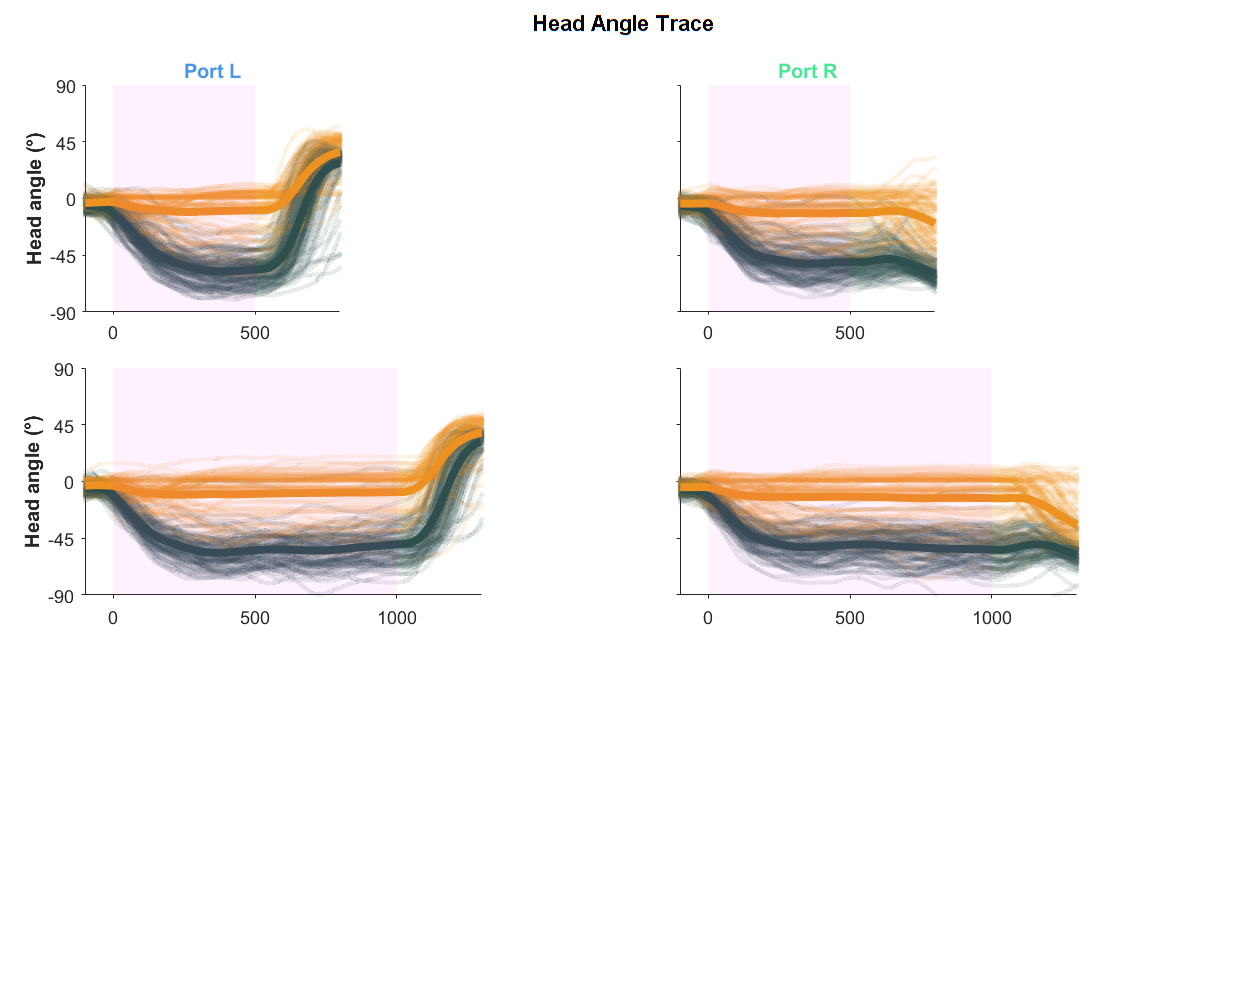

fig_trace = figure(52); clf(52);
set(fig_trace, 'Units', 'Centimeters', 'Position', [1 1 22 17.5], 'PaperPositionMode', 'Auto', 'Color', 'w');

uicontrol('Style', 'text', 'parent', fig_trace, 'units', 'normalized', 'position', [0.2 0.96 0.6 0.03],...
    'string', "Head Angle Trace", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

plot_height = 4;
plot_width  = [9 14 19] / 2;

for i = 1:2

    for j = 1:2

        ax_trace = axes;
        set(ax_trace, 'Units', 'Centimeters', 'Position', [1.5+10.5*(j-1) 12-5*(i-1) plot_width(i) plot_height], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

        fp_begin = 0;
        fp_end   = 1000*obj.MixedFPs(i);

        these_trials = find(obj.TrialInfo.Performance=="Correct" & obj.TrialInfo.PortChosen==obj.Ports(j) & obj.TrialInfo.FP==obj.MixedFPs(i) & obj.TrialInfo.Stage==1);
        these_trials = these_trials(randperm(length(these_trials)));
        these_trials_control = these_trials(obj.TrialInfo.Label(these_trials)=="Control");
        these_trials_chemo = these_trials(obj.TrialInfo.Label(these_trials)=="Chemo");

        for k = 1:length(these_trials)
            switch obj.TrialInfo.Label(these_trials(k))
                case "Chemo"
                    color_this = GPSColor.Treat;
                case "Control"
                    color_this = GPSColor.Control;
            end
            patch(ax_trace, 'XData', [obj.TimePointsIn(1:100+1000*obj.MixedFPs(i)+300) nan], 'YData', [obj.AngleHeadMatIn(these_trials(k), (1:100+1000*obj.MixedFPs(i)+300)) nan], 'EdgeColor', color_this, 'EdgeAlpha', 0.1, 'LineWidth', 2)
        end

        plot(ax_trace, obj.TimePointsIn(1:100+1000*obj.MixedFPs(i)+300), mean(obj.AngleHeadMatIn(these_trials_control, 1:100+1000*obj.MixedFPs(i)+300)), ...
            'Color', GPSColor.Control, 'LineWidth', 4)

        plot(ax_trace, obj.TimePointsIn(1:100+1000*obj.MixedFPs(i)+300), mean(obj.AngleHeadMatIn(these_trials_chemo, 1:100+1000*obj.MixedFPs(i)+300)), ...
            'Color', GPSColor.Treat, 'LineWidth', 4)

        patch(ax_trace, 'XData', [fp_begin fp_end fp_end fp_begin], 'YData', [-90 -90 90 90], 'FaceColor', 'm', 'FaceAlpha', 0.05, 'EdgeColor', 'none')

        set(ax_trace, 'XLim', [-100 1000*obj.MixedFPs(i)+300], 'YLim', [-90 90], 'XTick', 0:500:1500, 'YTick', -90:45:90);
        if i == 3
            ax_trace.XLabel.String = "Time from poke-in center (ms)";
            ax_trace.XLabel.FontWeight = "bold";
        end
        if i == 1
            ax_trace.Title.String = "Port "+obj.Ports(j);
            ax_trace.Title.Color  = GPSColor.("Port"+obj.Ports(j));
            ax_trace.Title.FontWeight = "bold";
        end
        if j == 1
            ax_trace.YLabel.String = "Head angle (°)";
            ax_trace.YLabel.FontWeight = "bold";
        end
        if j == 2
            ax_trace.YTickLabel = [];
        end

    end

end
save_name = "HeadAngleTrace_" + obj.ANM + "_" + obj.Task + ".jpg";
save_path = fullfile(AnmDir, save_name);
saveas(fig_trace, save_path);

M_z = zscore(M(:));
M_z = reshape(M_z, size(M));


dtw_distances = zeros(size(M_z, 1), size(M_z, 1));
for i = 1:size(M_z, 1)
    for j = i+1:size(M_z, 1)
        dtw_distances(i, j) = dtw(M_z(i, :), M_z(j, :));
    end
end
% 填充对称位置
dtw_distances = dtw_distances + dtw_distances';


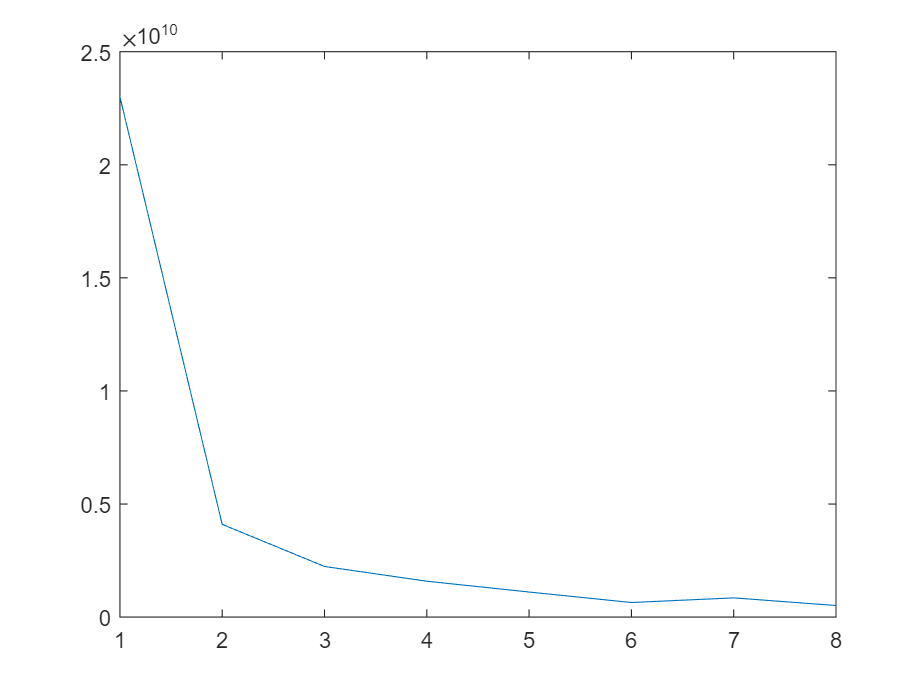

Cost = zeros(1, 8);
for k = 1:8
    % 使用K-Means聚类
    num_clusters = k; % 指定聚类数
    [~, ~, sumd] = kmeans(dtw_distances, num_clusters);
    Cost(k) = sum(sumd);
end
figure()
plot(1:8, Cost)

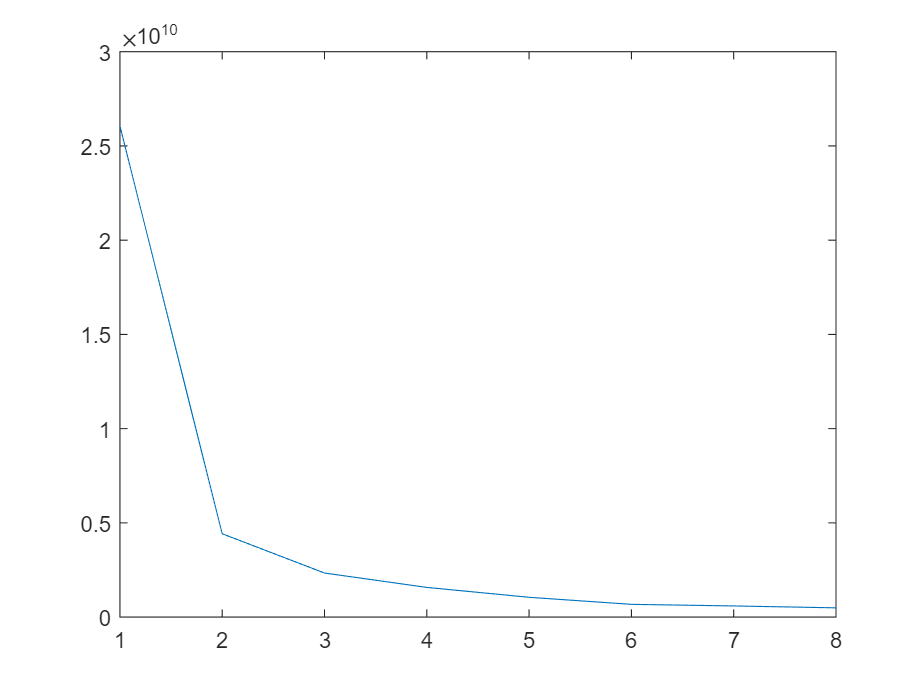

Cost = zeros(1, 8);
for k = 1:8
    % 使用K-Means聚类
    num_clusters = k; % 指定聚类数
    [~, ~, sumd] = kmedoids(dtw_distances, num_clusters);
    Cost(k) = sum(sumd);
end
figure()
plot(1:8, Cost)

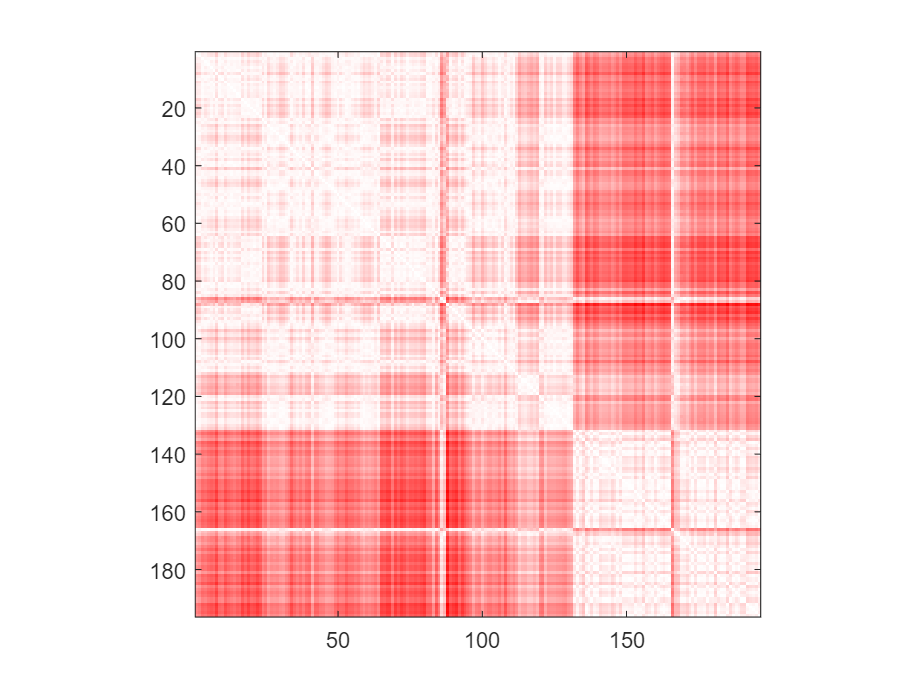

mycolormap = customcolormap([0 1], [1 0 0; 1 1 1]);

figure(); colormap(mycolormap)
imagesc(dtw_distances)
axis square

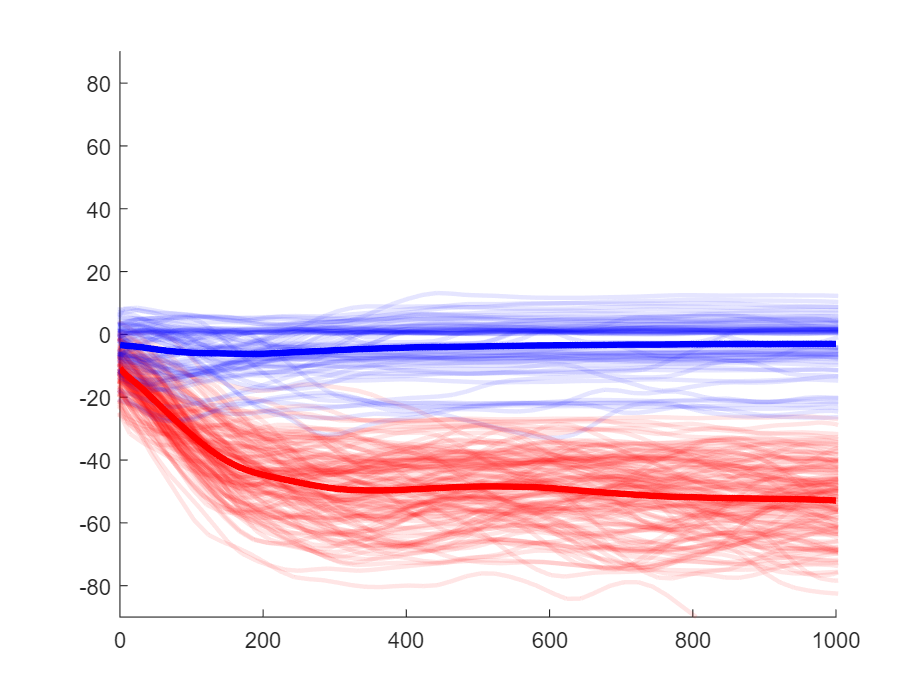

idx = kmedoids(dtw_distances, 2);

figure(); hold on;
c_1 = find(idx==1);
for i = 1:length(c_1)
    patch('XData', [0:1500 nan], 'YData', [M(c_1(i), :) nan], 'EdgeColor', 'red', 'EdgeAlpha', 0.1, 'LineWidth', 2)
end

c_2 = find(idx==2);
for i = 1:length(c_2)
    patch('XData', [0:1000 nan], 'YData', [M(c_2(i), :) nan], 'EdgeColor', 'blue', 'EdgeAlpha', 0.1, 'LineWidth', 2)
end

plot(0:1000, mean(M(c_1, :), 1), '-r', 'LineWidth', 3);
plot(0:1000, mean(M(c_2, :), 1), '-B', 'LineWidth', 3);

ylim([-90 90])

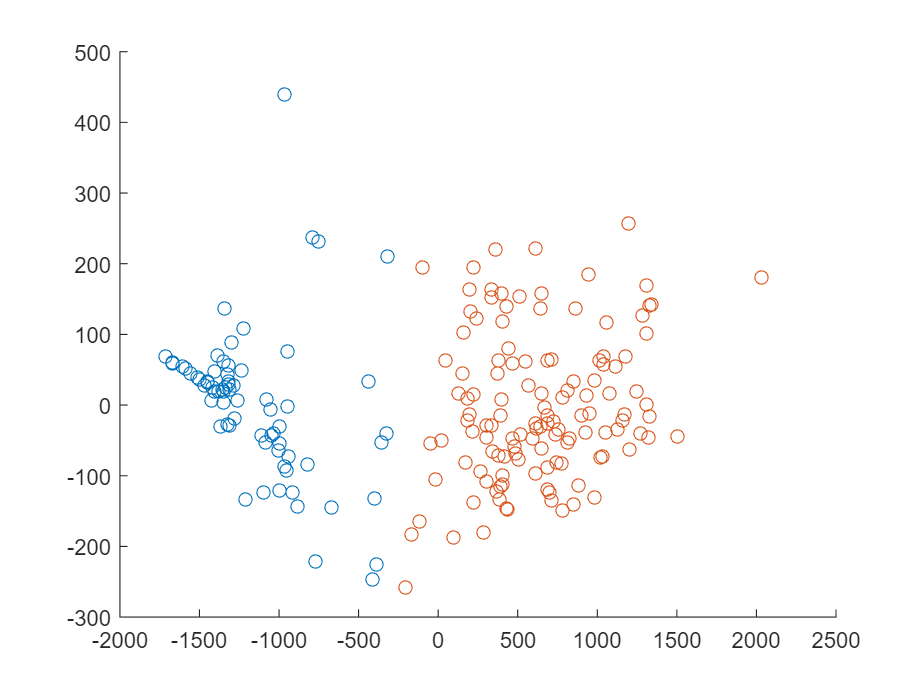

mds_score = cmdscale(dtw_distances, 2);

figure(); hold on;
scatter(mds_score(c_2,1), mds_score(c_2,2));
scatter(mds_score(c_1,1), mds_score(c_1,2));

squareform(dtw_distances)

ans = 1.0e+03 *

    0.0906    0.2775    0.2066    0.3807    0.4303    0.3577    0.7592    0.2522    0.1769    0.5181    0.3029    0.2684    0.2924    0.3177    0.2282    0.6724    0.3855    0.7137    0.5041    0.5333    0.7022    0.4932    0.1218    0.2408    0.0775    0.0630    0.1541    0.0685    0.1318    0.1139    0.1024    0.1482    0.5177    0.2660    0.1210    0.2322    0.1637    0.2479    0.3466    0.1789    0.2054    0.2317    0.1014    0.1586    0.1180    0.0983    0.0633    0.1589    0.3317    0.1786


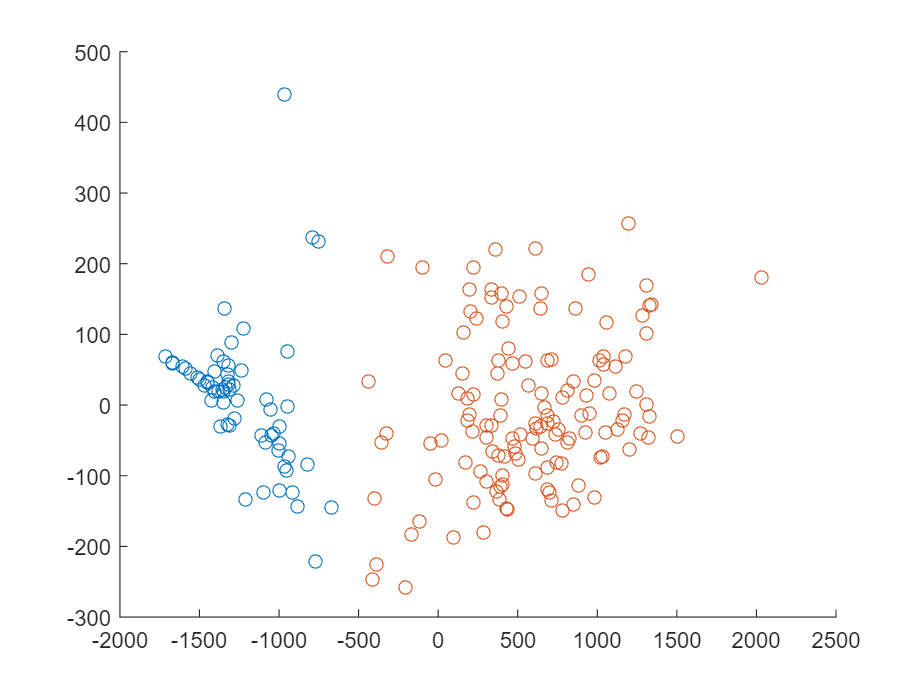


Z = linkage(squareform(dtw_distances));

T = cluster(Z,'maxclust',2);

[mds_score, eigvals] = cmdscale(dtw_distances);

figure(); hold on;
scatter(mds_score(T==1,1), mds_score(T==1,2));
scatter(mds_score(T==2,1), mds_score(T==2,2));

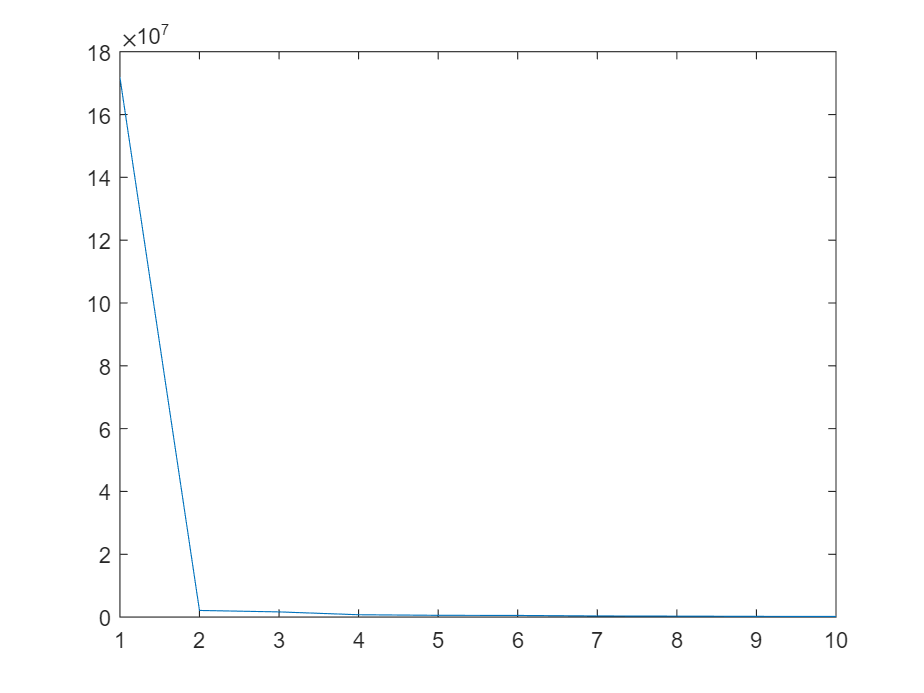

figure();
plot(eigvals(1:10))

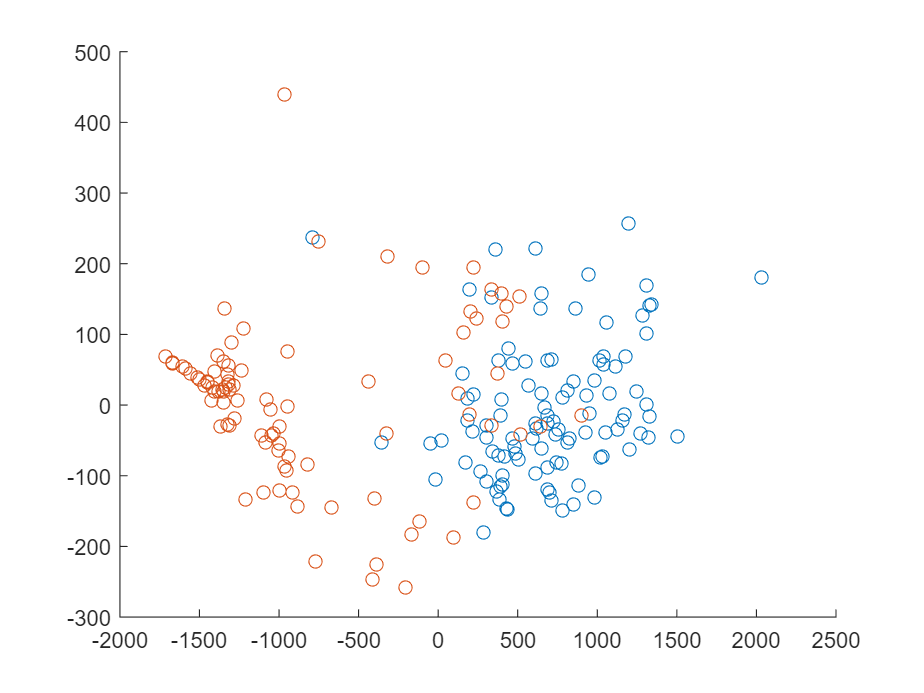

id_control = 1:length(these_trials_control);
id_chemo = length(these_trials_control) + (1:length(these_trials_chemo));

figure(); hold on;
scatter(mds_score(id_control,1), mds_score(id_control,2));
scatter(mds_score(id_chemo,1), mds_score(id_chemo,2));

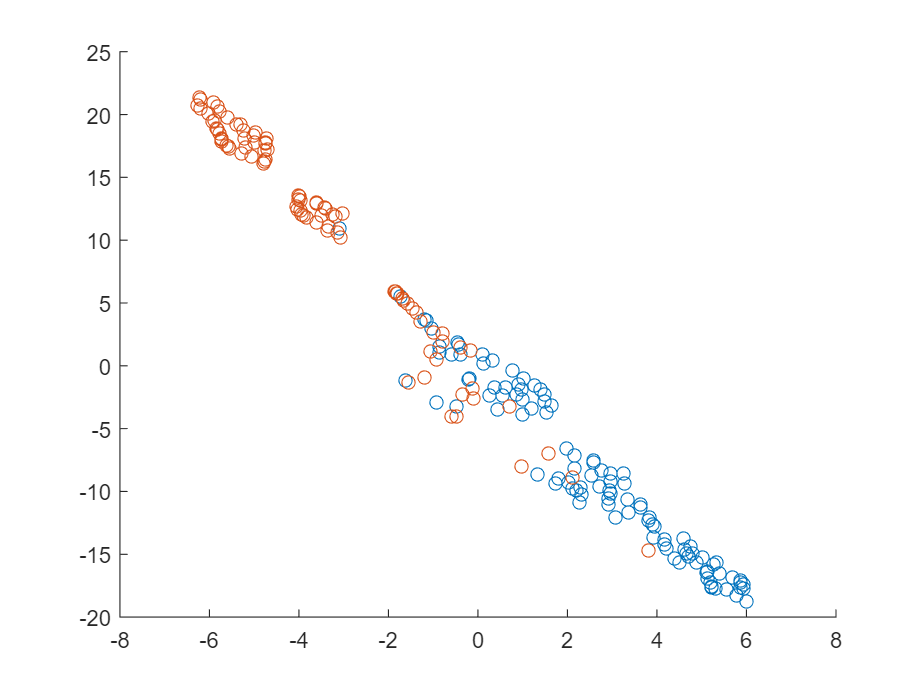

tsne_score = tsne(dtw_distances, 'Algorithm', 'exact');
figure(); hold on;
scatter(tsne_score(id_control,1), tsne_score(id_control,2));
scatter(tsne_score(id_chemo,1), tsne_score(id_chemo,2));

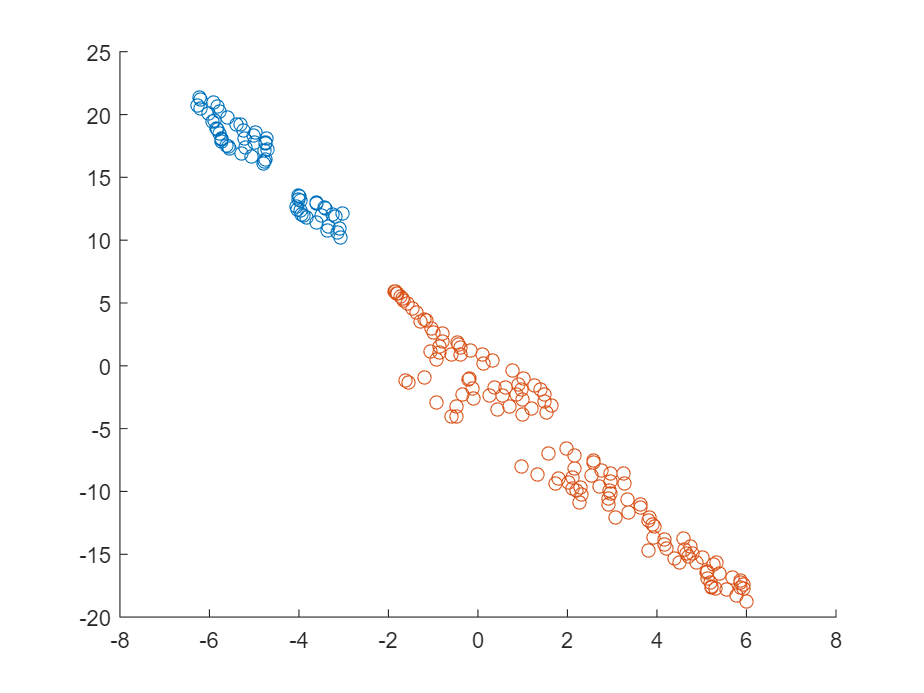

figure(); hold on;
scatter(tsne_score(T==1,1), tsne_score(T==1,2));
scatter(tsne_score(T==2,1), tsne_score(T==2,2));

tsne_d_score = tsne_d(dtw_distances);

Mean value of sigma: 0.032668
Minimum value of sigma: 0.012694
Maximum value of sigma: 0.1092
Iteration 10: error is 34.8548
Iteration 20: error is 32.2557
Iteration 30: error is 31.907
Iteration 40: error is 31.5863
Iteration 50: error is 31.2061
Iteration 60: error is 31.3015
Iteration 70: error is 31.0998
Iteration 80: error is 31.1303
Iteration 90: error is 31.8618
Iteration 100: error is 1.3262
Iteration 110: error is 0.41006
Iteration 120: error is 0.24517
Iteration 130: error is 0.23799
Iteration 140: error is 0.23634
Iteration 150: error is 0.23544
Iteration 160: error is 0.23466
Iteration 170: error is 0.2342
Iteration 180: error is 0.2338
Iteration 190: error is 0.23365
Iteration 200: error is 0.23331
Iteration 210: error is 0.23309
Iteration 220: error is 0.23294
Iteration 230: error is 0.23279
Iteration 240: error is 0.23268
Iteration 250: error is 0.23255
Iteration 260: error is 0.23237
Iteration 270: error is 0.23209
Iteration 280: error is 0.23187
Iteration 290: error is

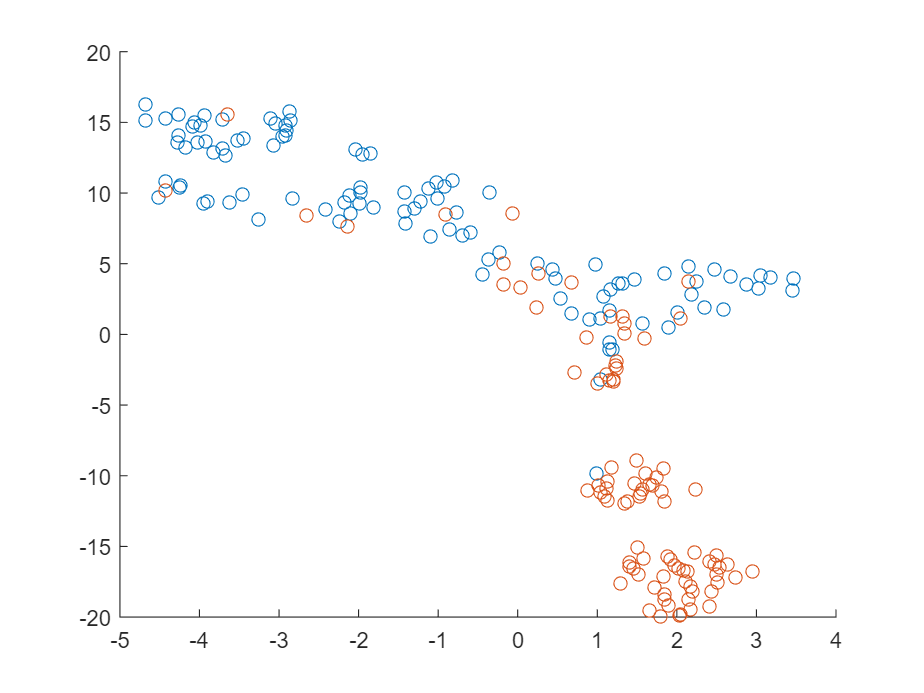

figure(); hold on;
scatter(tsne_d_score(id_control,1), tsne_d_score(id_control,2));
scatter(tsne_d_score(id_chemo,1), tsne_d_score(id_chemo,2));

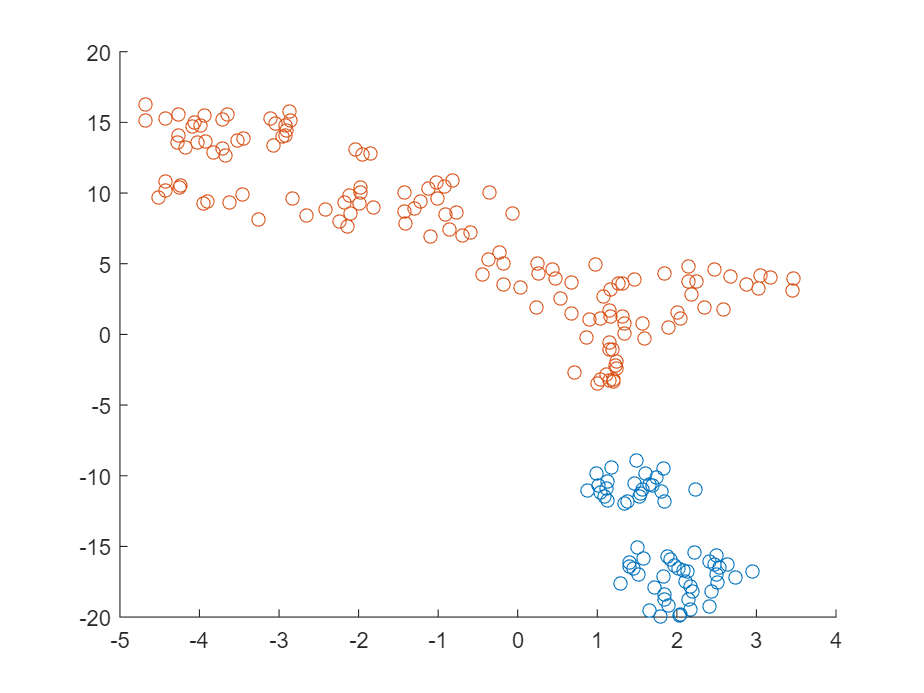

figure(); hold on;
scatter(tsne_d_score(T==1,1), tsne_d_score(T==1,2));
scatter(tsne_d_score(T==2,1), tsne_d_score(T==2,2));

y = [zeros(length(id_control), 1); ones(length(id_chemo), 1)];
x = mds_score;



n_wor = 0;
% leave-one-out
for i = 1:length(y)

    id_test = i;
    id_train = setdiff(1:length(y), id_test);

    mdl_svm = fitcsvm(x(id_train, :), y(id_train));

    y_pred = predict(mdl_svm, x(id_test, :));
    n_wor = n_wor + abs(y_pred - y(id_test));

end

1 - n_wor / length(y)

ans = 0.8469

cvp = cvpartition(y, 'KFold', 10);

cvError = crossval('mcr', x, y, 'Predfun', @classf, 'Partition', cvp);
accuracy = 1 - cvError

accuracy = 0.8776

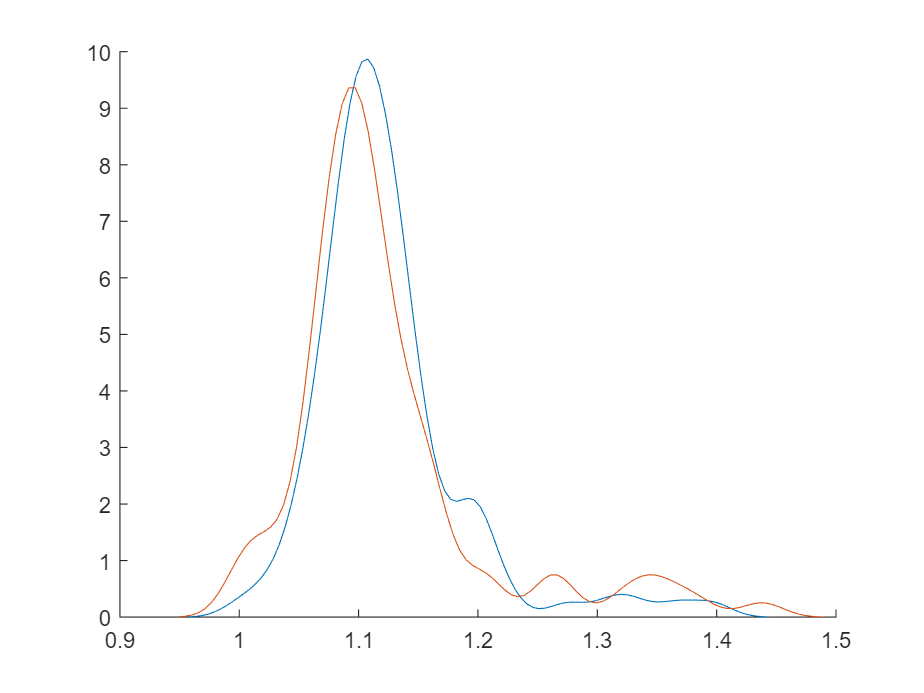

hd_control = obj.HD(these_trials_control);
hd_chemo = obj.HD(these_trials_chemo);
hd = [hd_control hd_chemo];

figure(); hold on;
ksdensity(hd_control); ksdensity(hd_chemo);

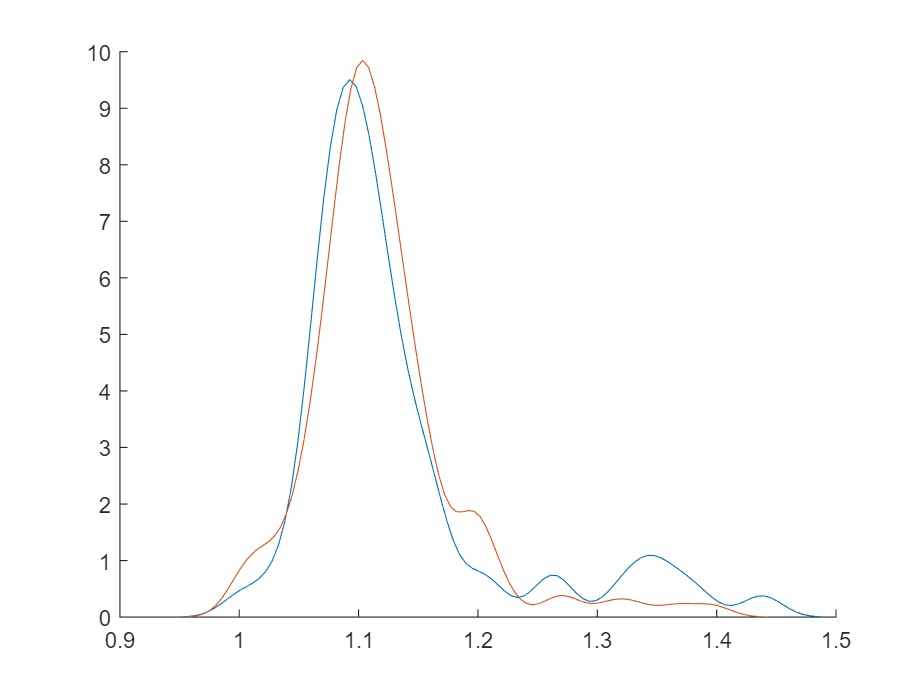

figure(); hold on;
ksdensity(hd(T==1)); ksdensity(hd(T==2));

function y_fit = classf(x_train, y_train, x_test)
    
    mdl = fitcdiscr(x_train, y_train);
    y_fit = predict(mdl, x_test);

end



